# AB Behavior Analysis

maxcells=13;
[R]=ExtractData_AB(0,maxcells);
save('R', 'R'); %save('behavior', 'behavior')
%sanity check
%for amigo3

plot(R.Pos.x1,R.Pos.y1)

makeEvsMatrix

load('R.mat')
numTetrodes=size(R.Spike.x);
for tetrode=1:numTetrodes(2)
    for unit=1:length(R.Spike.x)
        if isempty(R.Spike.x{unit,tetrode})
        else
            fullSplitAB(tetrode,unit,R.Pos.x1,R.Pos.y1,R.Pos.t,R.Spike.x(unit,tetrode),R.Spike.y(unit,tetrode),R.Spike.t(unit,tetrode),R.TimeStamps,R.mapAxis,R.p,R.visited)
            cd ..
        end
    end
end

clearvars

list_cells=num2str(ls('TT*unit*'));
sessions={'ab' 'ba' 'empty'};

for aa=1:length(list_cells)
    cd(list_cells(aa,1:end));
    load('Split.mat')
    for bb=1:length(sessions)
        thisSession=sessions(bb);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        posx=eval(strcat('Split.',thisSession,'.posx'));
        posy=eval(strcat('Split.',thisSession,'.posy'));
        post=eval(strcat('Split.',thisSession,'.post'));
        spkx=eval(strcat('Split.',thisSession,'.spkx'));
        spky=eval(strcat('Split.',thisSession,'.spky'));
        figure(aa)
        subplot(1,length(sessions),bb)
        plot(posx,posy,'k');hold on; plot(spkx,spky,'.r')
        axis('off')
        Title=strcat(list_cells(aa,1:end),sessions{bb});
        title(Title)
        daspect([1 1 1])
        savefig(figure(aa),'SpkPlots')  
    end
    close all
    cd ..
end

clearvars; load('R.mat')
list_cells=num2str(ls('TT*unit*'));
sessions={'ab' 'ba' 'empty'};

for aa=1:length(list_cells)
    cd(list_cells(aa,1:end));
    load('Split.mat')
    for bb=1:length(sessions)
        thisSession=sessions(bb);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        post=eval(strcat('Split.',thisSession,'.post'));
        posx=eval(strcat('Split.',thisSession,'.posx'));post(isnan(posx))=[];posx(isnan(posx))=[];
        posy=eval(strcat('Split.',thisSession,'.posy'));posy(isnan(posy))=[];
        spkx=eval(strcat('Split.',thisSession,'.spkx'));spkx(isnan(spkx))=[];
        spky=eval(strcat('Split.',thisSession,'.spky'));spky(isnan(spky))=[];
        figure(aa)
        subplot(1,length(sessions),bb)
        
        set(gcf,'color',[1 1 1]);
        axis square
        drawnow;
        
    %define mapaxis
        [map,pospdf] = ratemap(spkx,spky,posx,posy,post,R.p.smoothing,R.mapAxis,R.mapAxis);
        [nFields.hab,fieldProp.hab] = placefield(map,R.p,R.mapAxis);
        map(R.visited==0) = NaN;
        
        if R.p.plotratemap == 1
        drawfield(map,R.mapAxis,'jet',max(max(map)),R.p.binWidth,R.p.smoothing);
       
        else
        surfc(map);
         
        end
        
        set(gcf,'color',[1 1 1]);
        axis image;
        set(gca,'xtick',[]);set(gca,'ytick',[])
        f = getframe(gcf);
        [pic, cmap] = frame2im(f);

        Title=strcat(list_cells(aa,1:end),sessions{bb});
        xlabel(Title)
        daspect([2 2 1])
        savefig(figure(aa),'HeatMaps')  
    end
    close all
    cd ..
end

clearvars
tic
list_cells=num2str(ls('TT*unit*'));
vel=.5;
sessions={'ab', 'ba', 'empty'};
load('R.mat')
corr_mat=cell(length(list_cells),5);
for i=1:length(list_cells)
    thisCell=list_cells(i,1:end);
    cd(thisCell)
    load('Split.mat')
    for j=1:length(sessions)
        thisSession=sessions{j};
        post=eval(strcat('Split.',thisSession,'.post'));
        posx=eval(strcat('Split.',thisSession,'.posx'));post(isnan(posx))=[];posx(isnan(posx))=[];
        posy=eval(strcat('Split.',thisSession,'.posy'));posy(isnan(posy))=[];
        spkx=eval(strcat('Split.',thisSession,'.spkx'));spkx(isnan(spkx))=[];
        spky=eval(strcat('Split.',thisSession,'.spky'));spky(isnan(spky))=[];
 
        [thismap,~] = ratemap(spkx,spky,posx,posy,post,R.p.smoothing,R.mapAxis,R.mapAxis);

        thismap(isnan(thismap))=[];
        corr_mat{i,j}=thismap;
    end
    cd ..
    
end
toc

Elapsed time is 16.037664 seconds.



save('corr_mat','corr_mat')

%now use corr_mat to look at spatial correlation between sessions
sess_corr=zeros(length(corr_mat),(length(sessions)-1));
p_vals=zeros(length(corr_mat),(length(sessions)-1));
for ii=1:length(list_cells)
    for jj=1:length(sessions)-1
        sess1=corr_mat{ii,jj};
        sess2=corr_mat{ii,jj+1};
        [r,p]=corrcoef(sess1,sess2);
        pop_corr(ii,jj)=r(2,1);
        p_vals(ii,jj)=p(2,1);
    end
end

save('pop_corr','pop_corr')

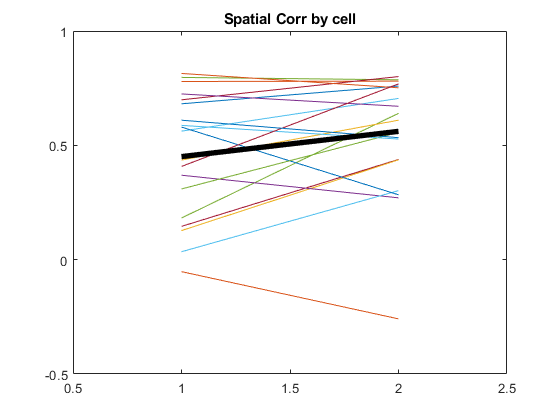

figure()
 for i=1:length(list_cells)
    plot(pop_corr(i,:))
    hold on
    axis([.5 2.5 -.5 1])
end
plot(mean(pop_corr),'k','linewidth',4) 
title('Spatial Corr by cell')